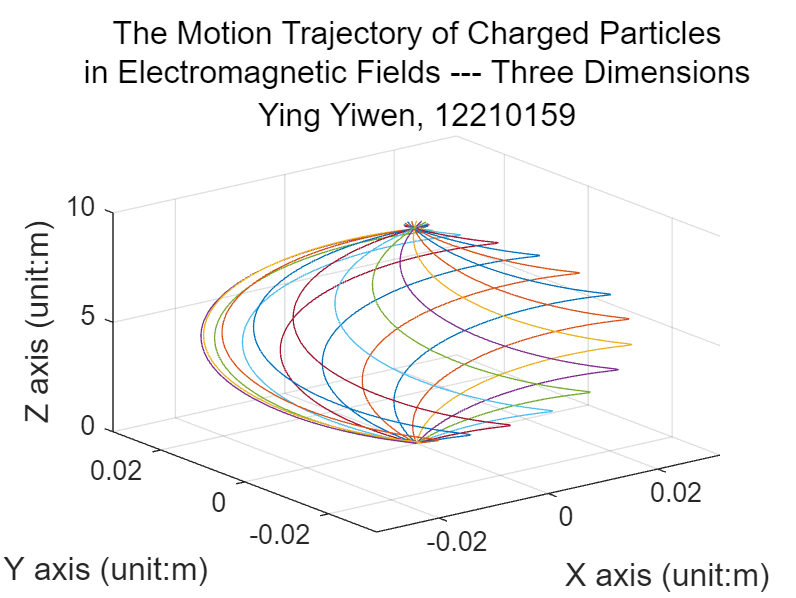

clc,clear,close all;
% parameters
m=0.02; % charge mass
q=1.6e-2; % charge quantity
dt=0.001; % time division
t=0:dt:1; % time array
vx=linspace(0,0,length(t)); % velocity x
vy=vx; % velocity y
vz=vx; % velocity z
rx=linspace(0,0,length(t)); % position x
ry=rx; % position y
rz=rx; % position z
Ex=0; % electric field intensity x
Ey=0; % electric field intensity y
Ez=0; % electric field intensity z
Bx=0; % magnetic field intensity x
By=0; % magnetic field intensity y
Bz=8; % magnetic field intensity z
Fx=linspace(0,0,length(t)); % force vector x
Fy=Fx; % force vetor y
Fz=Fx; % force vetor z
ax=linspace(0,0,length(t)); % accelerate x
ay=ax; % accelerate y
az=ax; % accelerate z

%draw
figure;
hold on; % keep the figure
grid on; % open the grid
title(sprintf('The Motion Trajectory of Charged Particles\nin Electromagnetic Fields --- Three Dimensions'),'Ying Yiwen, 12210159','FontSize',12); % title
xlabel('X axis (unit:m)','FontSize',12); % x label
ylabel('Y axis (unit:m)','FontSize',12); % y label
zlabel('Z axis (unit:m)','FontSize',12); % z label
view(3); % set the graph to be three dimension
set(gcf,'Position',[360 178 560 420]); % adjust graph size

%compute
for k = 0:15
    vx(1)=0.1*sin(k*pi/8); % velocity x init
    vy(1)=0.1*cos(k*pi/8); % velocity y init
    vz(1)=10; % velocity z init
    for i = 1:(length(t)-1)
        Fx(i)=q*Ex+q*(vy(i)*Bz-vz(i)*By); % force x i
        Fy(i)=q*Ey+q*(vx(i)*Bx-vx(i)*Bz); % force y i
        Fz(i)=q*Ez+q*(vx(i)*By-vy(i)*Bx); % force z i
        ax(i)=Fx(i)/m; % accelerate x i
        ay(i)=Fy(i)/m; % accelerate y i
        az(i)=Fz(i)/m; % accelerate z i
        vx(i+1)=vx(i)+ax(i)*dt; % velocity x i+1
        vy(i+1)=vy(i)+ay(i)*dt; % velocity y i+1
        vz(i+1)=vz(i)+az(i)*dt; % velocity z i+1
        rx(i+1)=rx(i)+vx(i)*dt; % position x i+1
        ry(i+1)=ry(i)+vy(i)*dt; % position y i+1
        rz(i+1)=rz(i)+vz(i)*dt; % position z i+1
    end
    plot3(rx,ry,rz); % plot the figure
end
saveas(gcf,'fig-1-1.jpg'); % save figure

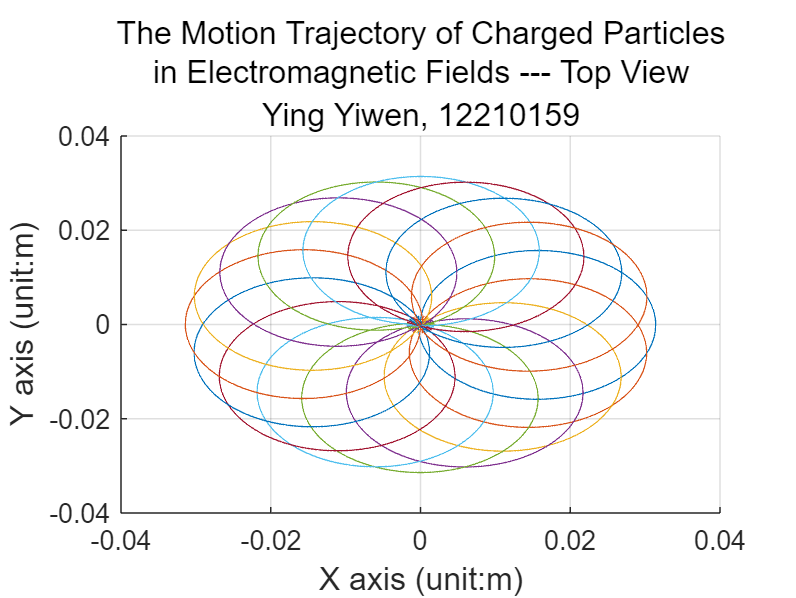


%draw
figure;
hold on; % keep the figure
grid on; % open the grid
title(sprintf('The Motion Trajectory of Charged Particles\nin Electromagnetic Fields --- Top View'),'Ying Yiwen, 12210159','FontSize',12); % title
xlabel('X axis (unit:m)','FontSize',12); % x label
ylabel('Y axis (unit:m)','FontSize',12); % y label

%compute
for k = 0:15
    vx(1)=0.1*sin(k*pi/8); % velocity x init
    vy(1)=0.1*cos(k*pi/8); % velocity y init
    vz(1)=10; % velocity z init
    for i = 1:(length(t)-1)
        Fx(i)=q*Ex+q*(vy(i)*Bz-vz(i)*By); % force x i
        Fy(i)=q*Ey+q*(vx(i)*Bx-vx(i)*Bz); % force y i
        Fz(i)=q*Ez+q*(vx(i)*By-vy(i)*Bx); % force z i
        ax(i)=Fx(i)/m; % accelerate x i
        ay(i)=Fy(i)/m; % accelerate y i
        az(i)=Fz(i)/m; % accelerate z i
        vx(i+1)=vx(i)+ax(i)*dt; % velocity x i+1
        vy(i+1)=vy(i)+ay(i)*dt; % velocity y i+1
        vz(i+1)=vz(i)+az(i)*dt; % velocity z i+1
        rx(i+1)=rx(i)+vx(i)*dt; % position x i+1
        ry(i+1)=ry(i)+vy(i)*dt; % position y i+1
        rz(i+1)=rz(i)+vz(i)*dt; % position z i+1
    end
    plot(rx,ry); % plot the figure
end
saveas(gcf,'fig-1-2.jpg'); % save figure

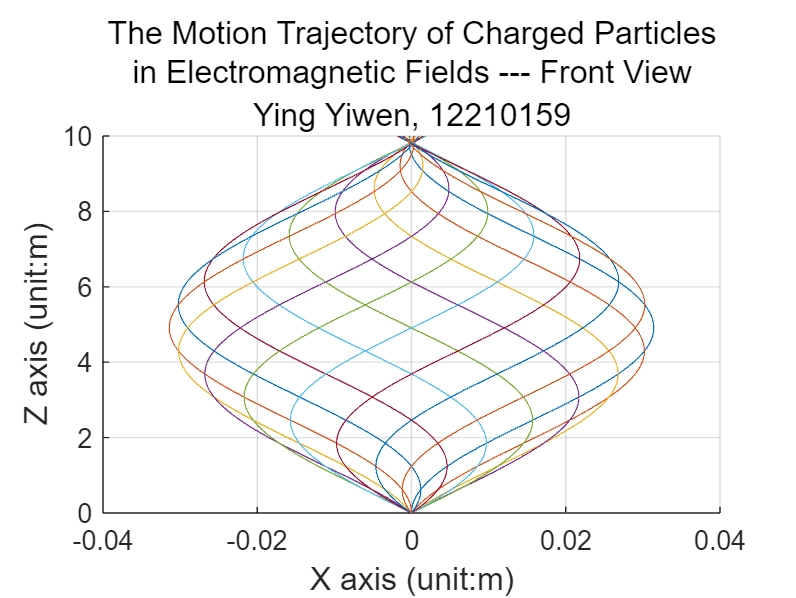


%draw
figure;
hold on; % keep the figure
grid on; % open the grid
title(sprintf('The Motion Trajectory of Charged Particles\nin Electromagnetic Fields --- Front View'),'Ying Yiwen, 12210159','FontSize',12); % title
xlabel('X axis (unit:m)','FontSize',12); % x label
ylabel('Z axis (unit:m)','FontSize',12); % z label
set(gcf,'Position',[360 178 560 420]); % adjust graph size

%compute
for k = 0:15
    vx(1)=0.1*sin(k*pi/8); % velocity x init
    vy(1)=0.1*cos(k*pi/8); % velocity y init
    vz(1)=10; % velocity z init
    for i = 1:(length(t)-1)
        Fx(i)=q*Ex+q*(vy(i)*Bz-vz(i)*By); % force x i
        Fy(i)=q*Ey+q*(vx(i)*Bx-vx(i)*Bz); % force y i
        Fz(i)=q*Ez+q*(vx(i)*By-vy(i)*Bx); % force z i
        ax(i)=Fx(i)/m; % accelerate x i
        ay(i)=Fy(i)/m; % accelerate y i
        az(i)=Fz(i)/m; % accelerate z i
        vx(i+1)=vx(i)+ax(i)*dt; % velocity x i+1
        vy(i+1)=vy(i)+ay(i)*dt; % velocity y i+1
        vz(i+1)=vz(i)+az(i)*dt; % velocity z i+1
        rx(i+1)=rx(i)+vx(i)*dt; % position x i+1
        ry(i+1)=ry(i)+vy(i)*dt; % position y i+1
        rz(i+1)=rz(i)+vz(i)*dt; % position z i+1
    end
    plot(rx,rz); % plot the figure
end
saveas(gcf,'fig-1-3.jpg'); % save figure